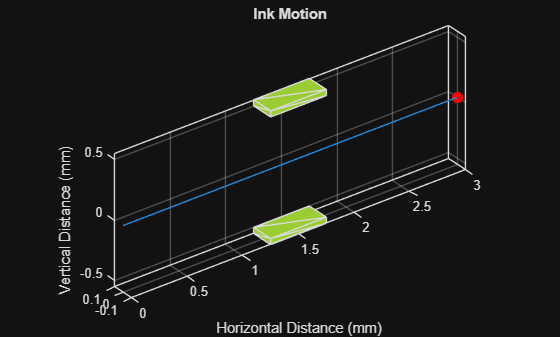

clear all
%----Given Values-------
d = 84 * 10^-6;     %Diameter of droplet (m)
r = 42 * 10^-6;     %Radius of droplet (m)
D = 3 *10^-3;       %Distance to paper (m)
vx = 20;            %Velocity in x direction (m/s)
L1 = 0.5 * 10^-3;   %Length of Capacitor (m)
L2 = 1.25 * 10^-3;  %Distance between paper and cap (m)
q = -1.9*10^-10;    %Charge of electron (C)
pd = 1000;          %Density of droplet (kg/m^3)
W = 1 *10^-3;       %Diameter between Cap plates (m)
vy = 0;

%------Equations------
T = L1 / vx;        %Droplet time in capacitor
m = pd * (4/3)*pi*(r)^3;  %Mass of droplet
vf = sqrt(vx^2 + vy^2); %Velocity after exiting Cap

%----Part 1: No voltage--------------------------------------------

%----Condition values----
dt = .001;  %Time step
i = 1;
u = 1;
x1(1) = 0;
z1(1) = 0;

while x1(u) < 3
    % Update index
    i = i + 1;
    u = u + 1;

    % Calculate new positions
    x1(i) = x1(i-1) + vx * dt;
    z1(i) = z1(i-1) + vy * dt;

end

y1 = zeros(size(x1)); % Initialize z positions for 3D plot


width = .2;
height = .05;
Fa1 = 1.25;     %First face

% Define the vertices of the cuboid
P = [Fa1, width/2, .5;               %V1
     1.75, width/2, .5;
     1.75, -width/2, .5;
     Fa1, -width/2, .5;           %V4
     Fa1, width/2, height+.5;          %V5
     1.75, width/2, height+.5;
     1.75, -width/2, height+.5;
     Fa1, -width/2, height+.5];     %V8

Q = [Fa1, width/2, -.5;               %V1
     1.75, width/2, -.5;
     1.75, -width/2, -.5;
     Fa1, -width/2, -.5;           %V4
     Fa1, width/2, -height-.5;          %V5
     1.75, width/2, -height-.5;
     1.75, -width/2, -height-.5;
     Fa1, -width/2, -height-.5];     %V8

% Create the alphaShape object
alpha_radius = 3;
Tcap = alphaShape(P, alpha_radius);
Bcap = alphaShape(Q, alpha_radius);


figure;
plot3(x1,y1,z1)
view(3);
box on;
grid on;
title('Ink Motion');
xlabel('Horizontal Distance (mm)');
zlabel('Vertical Distance (mm)');
hold on;

plot(Tcap);
plot(Bcap);

xlim([0 3.5]);
axis equal;
% Animate the projectile
h = plot3(x1(1), y1(1), z1(1), 'ro', 'MarkerSize', 8, 'MarkerFaceColor', 'r');
for k = 1:i

    h.XData = x1(k);
    h.ZData = z1(k);

    drawnow;
    
end
hold off;

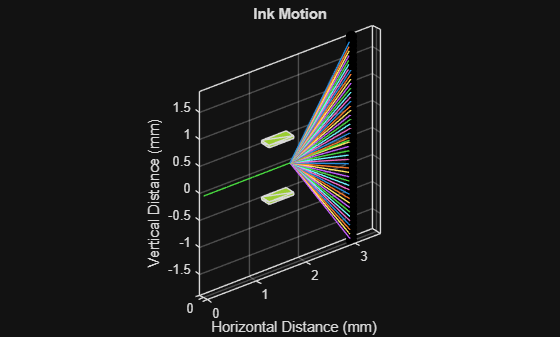


%----Part 2: Printing 'I'---------------------------------------------

%----Condition values----
dt = .000001;  %Time step
i = 1;
u = 1;
x(1) = 0;
z(1) = 0;
o = 1;

%The letter I at font 11 and 300 dpi will be 3.88mm tall

%Points is where the center of the droplet has to land on the paper
%Found by 3.88mm / 2 = 1.94mm --> 1.94mm - .042mm = 1.898mm
points(1) = 1.898;
%Example: points(2) = points(1) - radius of droplet
while points(o) > -1.94
    o = o + 1;
    points(o) = points(o-1) - d*10^3;
end

%Calculates the voltage for every location the droplet has to land on the
%paper
for it = 1:length(points)
    V(it) = (m*points(it)*(10^-3)*W*(vx)^2)/(q*L1*L2);
end

j = zeros(47,150001);   %Initialize the array for plotting the z-axis


for test = 1:46
    Vol = V(test);
    E = Vol / W;
    ay = q*E/m;

    %Reset indexes
    i = 1;
    u = 1;
    x(1) = 0;
    z(1) = 0;
    vy = 0;

    while x(u) < 3       %iterations in mm
        % Update index
        i = i + 1;
        u = u + 1;

        % Calculate new velocities (only y changes)
        if x(i-1) >= 1.75
            vy = ay * T;
        else
            vy = vy;
        end

        % Calculate new positions
        x(i) = x(i-1) + vx * dt;
        z(i) = z(i-1) + vy * dt;
        j(test,i) = z(i);
    
    end
end
y = zeros(size(x)); % Initialize z positions for 3D plot



%-------------Capacitor Display-------------------
width = .2;
height = .05;
Fa1 = 1.25;     %First face

% Define the vertices of the cuboid
P = [Fa1, width/2, .5;               %V1
     1.75, width/2, .5;
     1.75, -width/2, .5;
     Fa1, -width/2, .5;           %V4
     Fa1, width/2, height+.5;          %V5
     1.75, width/2, height+.5;
     1.75, -width/2, height+.5;
     Fa1, -width/2, height+.5];     %V8

Q = [Fa1, width/2, -.5;               %V1
     1.75, width/2, -.5;
     1.75, -width/2, -.5;
     Fa1, -width/2, -.5;           %V4
     Fa1, width/2, -height-.5;          %V5
     1.75, width/2, -height-.5;
     1.75, -width/2, -height-.5;
     Fa1, -width/2, -height-.5];     %V8

% Create the alphaShape object
alpha_radius = 3;
Tcap = alphaShape(P, alpha_radius);
Bcap = alphaShape(Q, alpha_radius);

%----------------------------------------------

figure;
plot3(x,y,j)
view(3);
box on;
grid on;
title('Ink Motion');
xlabel('Horizontal Distance (mm)');
zlabel('Vertical Distance (mm)');
hold on;

plot(Tcap);
plot(Bcap);
xlim([0 3.5]);

% Animate the projectile
for l = 1:46
    h = plot3(x(1), y(1), j(l,1), 'ko', 'MarkerSize', 8, 'MarkerFaceColor', 'k');
    for k = 1:10000:i

    h.XData = x(k);
    h.ZData = j(l,k);
    drawnow;
    
    end
end
hold off;

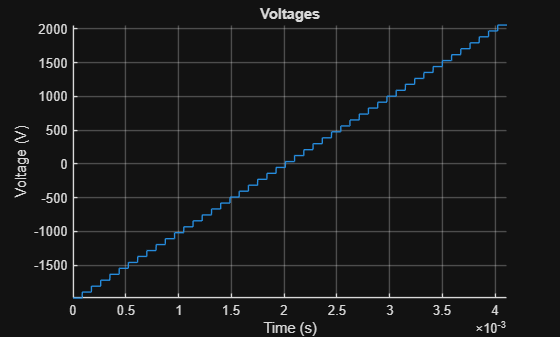


%----Part 3: Voltage Graph-----------------------------------------

tbd = (D - L2) / vx; % Time Between Droplets
Total_time = tbd * (length(V));

volt_time = 0:dt:Total_time;
vInd = 1;
test = 0;
t__t2 = 0;

for ind = 1:length(volt_time)
    VOT(ind) = V(vInd);

    %t__t2 = t__t2 + 1
    %mod(ind*dt, tbd)
    if mod(ind*dt, tbd) <= (dt/2 + dt/4)
        %test = test + 1
        vInd = vInd + 1;
    end
end

figure;
grid on;
title('Voltages');
xlabel('Time (s)');
xlim([0 Total_time])
ylabel('Voltage (V)');
ylim([V(1) V(47)])
hold on;

plot(volt_time, VOT)